# Galerkin's Method with Piecewise Polynomials

So far we have been approximating our solutions as a single polynomial function, which is infinitely smooth ($C^{\infty \;}$).  We saw, however, that as the solutions became more complex that we required ever-higher degree polynomials to accurately approximate them.  This can be challenging due to various concerns such as increasingly-poor conditioning and increased computational cost associated with increasing polynomial degree.  Furthermore, it's often the case that only a relatively small region of the domain requires the increased polynomial degree in order to improve accuracy of the approximation -- the higher degree polynomial is overkill for most of the domain while perhaps still underkill in a region of interest.

One way to address this issue is to introduce *piecewise* polynomials, that is, multiple polynomial functions each defined over some subdomain (piece) of the total domain.  We often refer to these pieces as *elements* or alternatively, as they are finite in both space (and time) as well as in the polynomial space, as *finite elements*.

We begin by first demonstrating an example of a piecewise polynomial:

clear
close all

x = sym( "x", "real" );
element_domain_1 = [0, 1];
element_domain_2 = [1, 2];
condition_1 = x >= element_domain_1(1) & x <= element_domain_1(2);
condition_2 = x >=  element_domain_2(1) & x <= element_domain_2(2);
function_1 = 1/2 * x + 1/2;
function_2 = x;
f(x) = piecewise( condition_1, function_1, condition_2, function_2 )

$$f(x) = \left\{ \begin{array}{cl} \frac{x}{2}+\frac{1}{2} & \text{ if }x\in \left[0,1\right]\\ x & \text{ if }x\in \left[1,2\right] \end{array}\right.$$

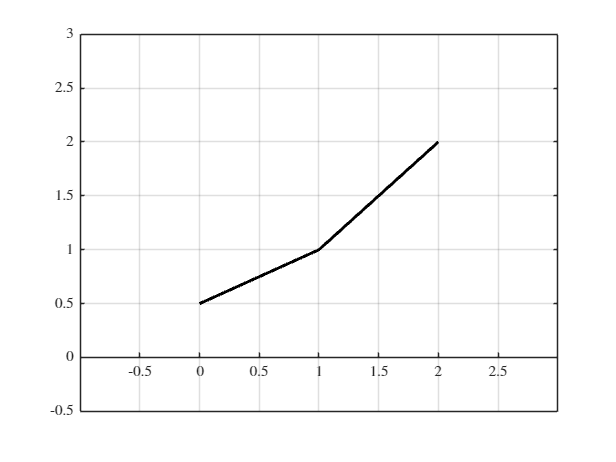


figure
fplot( f, [0, 2], LineWidth=2, Color="k" )
% xline( unique( [element_domain_1, element_domain_2] ), LineStyle="--" )
ax = gca;
ax.XAxisLocation = "origin";
ax.XGrid = "on";
ax.YGrid = "on";
axis( [-1, 3, -0.5, 3 ] )

But note that while this function is continuous ($C^0$) at the interface between the two elements, this need not be the case... here is another piecewise polynomial function that is *discontinuous* ($C^{-1}$)

clear

x = sym( "x", "real" );
element_domain_1 = [0, 1];
element_domain_2 = [1, 2];
condition_1 = x >= element_domain_1(1) & x <= element_domain_1(2);
condition_2 = x >=  element_domain_2(1) & x <= element_domain_2(2);
function_1 = 1/2 * x + 1/2;
function_2 = -x + 3;
f(x) = piecewise( condition_1, function_1, condition_2, function_2 )

$$f(x) = \left\{ \begin{array}{cl} \frac{x}{2}+\frac{1}{2} & \text{ if }x\in \left[0,1\right]\\ 3-x & \text{ if }x\in \left[1,2\right] \end{array}\right.$$

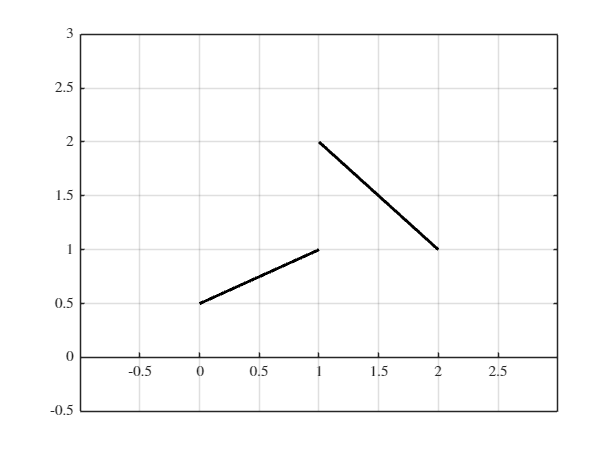


figure
hold on
fplot( f, [0, 1], LineWidth=2, Color="k" )
fplot( f, [1+eps(single(1)), 2], LineWidth=2, Color="k" )
% xline( unique( [element_domain_1, element_domain_2] ), LineStyle="--" )
ax = gca;
ax.XAxisLocation = "origin";
ax.XGrid = "on";
ax.YGrid = "on";
axis( [-1, 3, -0.5, 3 ] )

As each of the pieces of this piecewise function are polynomials, it follows that we can define a piecewise basis for both.  We begin with the discontinuous function

clear

x = sym( "x", "real" );
element_domain_1 = [0, 1];
element_domain_2 = [1, 2];
condition_1 = x >= element_domain_1(1) & x <= element_domain_1(2);
condition_2 = x >= element_domain_2(1) & x <= element_domain_2(2);
function_1 = 1/2 * x + 1/2;
function_2 = -x + 3;
f(x) = piecewise( condition_1, function_1, condition_2, function_2 )

$$f(x) = \left\{ \begin{array}{cl} \frac{x}{2}+\frac{1}{2} & \text{ if }x\in \left[0,1\right]\\ 3-x & \text{ if }x\in \left[1,2\right] \end{array}\right.$$


degree_1 = polynomialDegree( function_1 );
degree_2 = polynomialDegree( function_2 );
elem_basis_1 = PolynomialBasisFunction( "Lagrange", degree_1, x, element_domain_1 );
elem_basis_2 = PolynomialBasisFunction( "Lagrange", degree_2, x, element_domain_2 );
N = sym( zeros( 4, 1) );
N(1) = piecewise( condition_1, elem_basis_1(1) );
N(2) = piecewise( condition_1, elem_basis_1(2) );
N(3) = piecewise( condition_2, elem_basis_2(1) );
N(4) = piecewise( condition_2, elem_basis_2(2) );
display( N )

$$N = \left[\begin{array}{c} \left\{ \begin{array}{cl} 1-x & \text{ if }x\in \left[0,1\right] \end{array}\right.\\ \left\{ \begin{array}{cl} x & \text{ if }x\in \left[0,1\right] \end{array}\right.\\ \left\{ \begin{array}{cl} 2-x & \text{ if }x\in \left[1,2\right] \end{array}\right.\\ \left\{ \begin{array}{cl} x-1 & \text{ if }x\in \left[1,2\right] \end{array}\right. \end{array}\right]$$

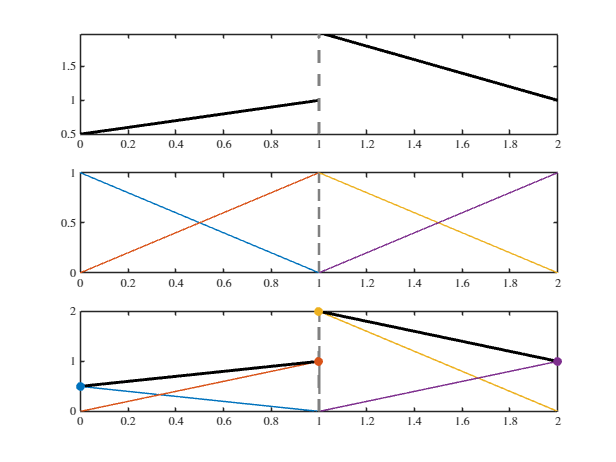

coeffs = [0.5; 1; 2; 1];

figure
subplot( 3, 1, 1 )
hold on
fplot( f, [0, 2], LineWidth=2, Color="k" )
subplot( 3, 1, 2 )
hold on
fplot( N, [0, 2] )
subplot( 3, 1, 3 )
hold on
fplot( coeffs .* N, [0, 2], LineWidth=1 )
fplot( f, [0, 2], LineWidth=2, Color="k" )
scatter( 0, coeffs(1), "filled", SeriesIndex=1 )
scatter( 1, coeffs(2), "filled", SeriesIndex=2 )
scatter( 1, coeffs(3), "filled", SeriesIndex=3 )
scatter( 2, coeffs(4), "filled", SeriesIndex=4 )

And now the continuous function

clear

x = sym( "x", "real" );
element_domain_1 = [0, 1];
element_domain_2 = [1, 2];
condition_1 = x >= element_domain_1(1) & x <= element_domain_1(2);
condition_2 = x > element_domain_2(1) & x <= element_domain_2(2);
function_1 = 1/2 * x + 1/2;
function_2 = x;
f(x) = piecewise( condition_1, function_1, condition_2, function_2 )

$$f(x) = \left\{ \begin{array}{cl} \frac{x}{2}+\frac{1}{2} & \text{ if }x\in \left[0,1\right]\\ x & \text{ if }x\in \left(1,2\right] \end{array}\right.$$


degree_1 = polynomialDegree( function_1 );
degree_2 = polynomialDegree( function_2 );
elem_basis_1 = PolynomialBasisFunction( "Lagrange", degree_1, x, element_domain_1 );
elem_basis_2 = PolynomialBasisFunction( "Lagrange", degree_2, x, element_domain_2 );
N = sym( zeros( 3, 1) );
N(1) = piecewise( condition_1, elem_basis_1(1) );
N(2) = piecewise( condition_1, elem_basis_1(2), condition_2, elem_basis_2(1) );
N(3) = piecewise( condition_2, elem_basis_2(2) );
display( N )

$$N = \left[\begin{array}{c} \left\{ \begin{array}{cl} 1-x & \text{ if }x\in \left[0,1\right] \end{array}\right.\\ \left\{ \begin{array}{cl} x & \text{ if }x\in \left[0,1\right]\\ 2-x & \text{ if }x\in \left(1,2\right] \end{array}\right.\\ \left\{ \begin{array}{cl} x-1 & \text{ if }x\in \left(1,2\right] \end{array}\right. \end{array}\right]$$

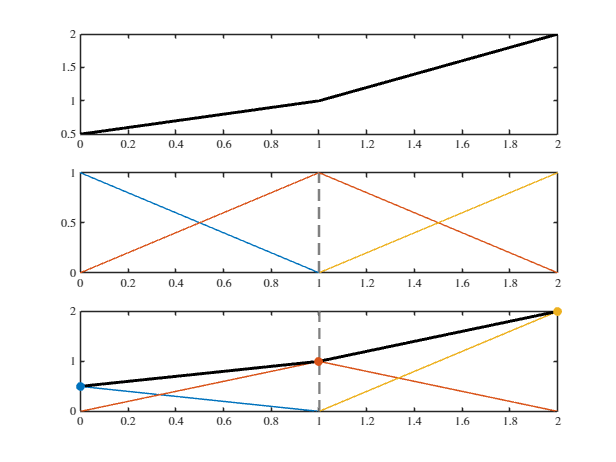

coeffs = [0.5; 1; 2];

figure
subplot( 3, 1, 1 )
hold on
fplot( f, [0, 2], LineWidth=2, Color="k" )
subplot( 3, 1, 2 )
hold on
fplot( N, [0, 2] )
subplot( 3, 1, 3 )
hold on
fplot( coeffs .* N, [0, 2], LineWidth=1 )
fplot( f, [0, 2], LineWidth=2, Color="k" )
scatter( 0, coeffs(1), "filled", SeriesIndex=1 )
scatter( 1, coeffs(2), "filled", SeriesIndex=2 )
scatter( 2, coeffs(3), "filled", SeriesIndex=3 )

For now, we need not concern ourselves with *how* we construct piecewise polynomial bases -- that's another topic for another time -- instead let's simply investigate what we can *do* with them as it pertains to approximation

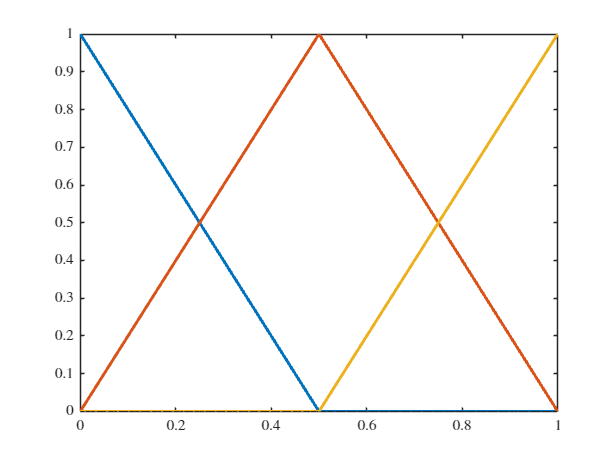

clear
close all

x = sym( "x", "real" );
degree = [1, 1];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 0 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x );

figure
fplot( basis.Basis, domain, LineWidth=2 )

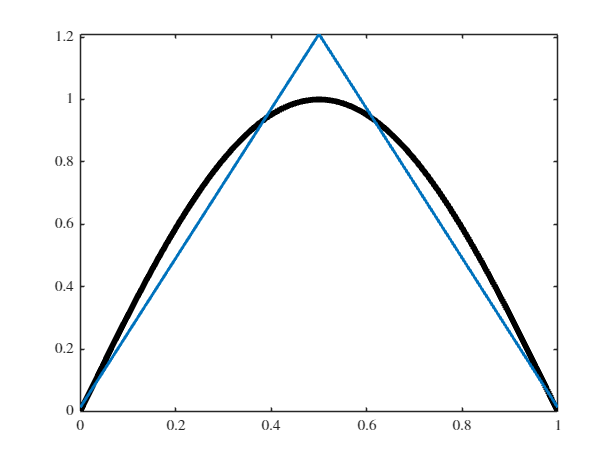


f = sin( pi * x );
[u, M, F, basis, d] = ScalarProjection( spline_space, f );

figure
hold on
fplot( f, domain, LineWidth=4, Color="k" )
fplot( u, domain, LineWidth=2, SeriesIndex=1 )

We can improve the approximation by adding more elements

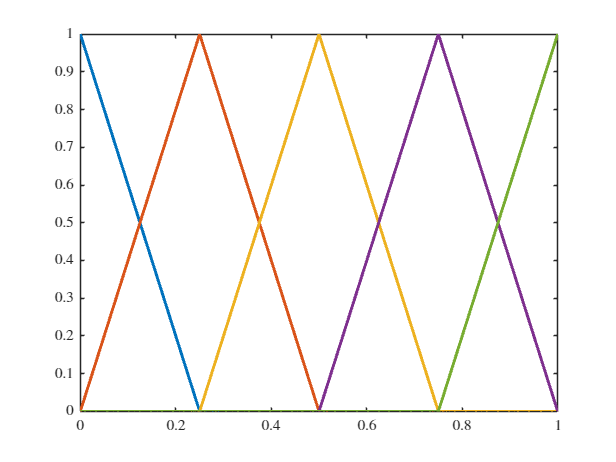

degree = [1, 1, 1, 1];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 0 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x );

figure
fplot( basis.Basis, domain, LineWidth=2 )

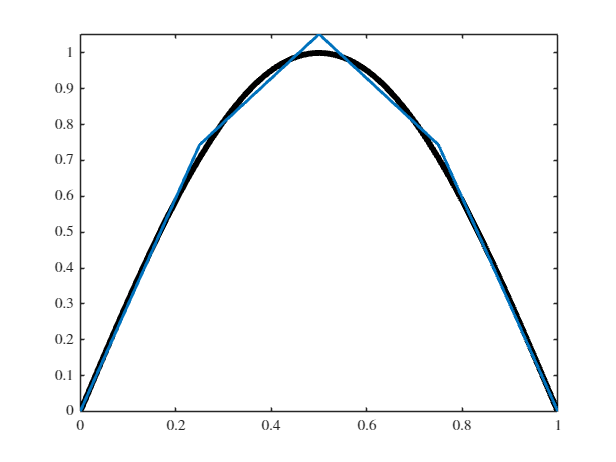


f = sin( pi * x );
[u, M, F, basis, d] = ScalarProjection( spline_space, f );

figure
hold on
fplot( f, domain, LineWidth=4, Color="k" )
fplot( u, domain, LineWidth=2, SeriesIndex=1 )

Or by increasing the degree of each element's polynomial basis:

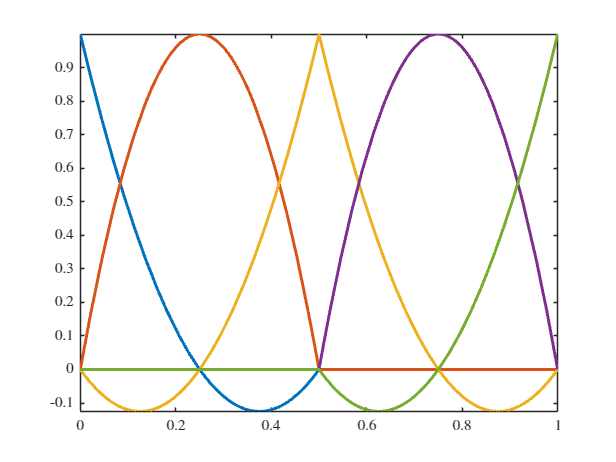

degree = [2, 2];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 0 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x );

figure
fplot( basis.Basis, domain, LineWidth=2 )

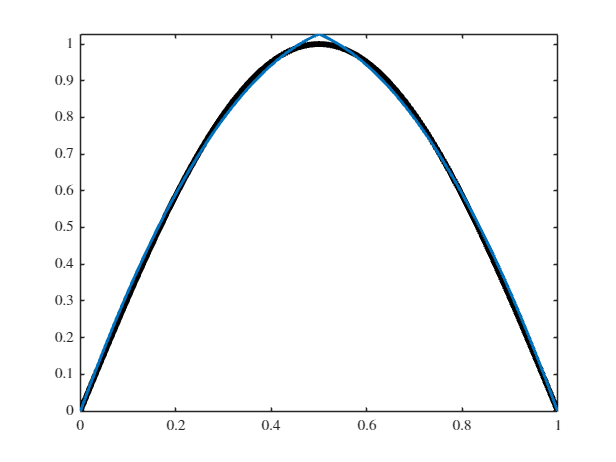


f = sin( pi * x );
[u, M, F, basis, d] = ScalarProjection( spline_space, f );

figure
hold on
fplot( f, domain, LineWidth=4, Color="k" )
fplot( u, domain, LineWidth=2, SeriesIndex=1 )

Or simultaneously increasing the number of elements and increasing the polynomial degree:

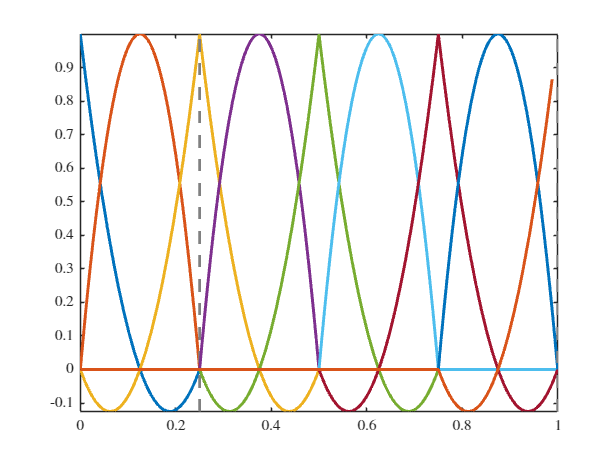

degree = [2, 2, 2, 2];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 0 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x );

figure
fplot( basis.Basis, domain, LineWidth=2 )

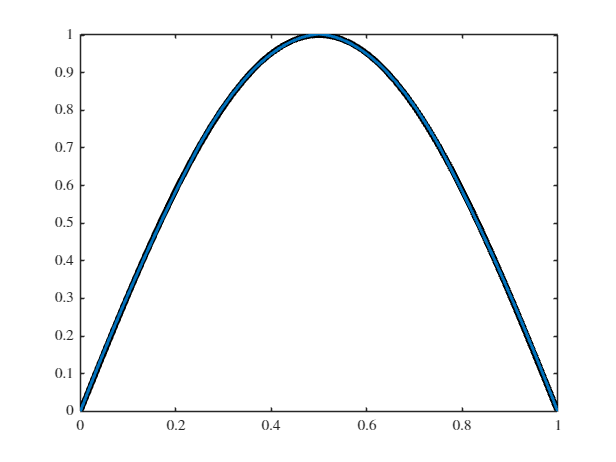


f = sin( pi * x );
[u, M, F, basis, d] = ScalarProjection( spline_space, f );

figure
hold on
fplot( f, domain, LineWidth=4, Color="k" )
fplot( u, domain, LineWidth=2, SeriesIndex=1 )

## Solving the Poisson Equation with Galerkin's Method using Piecewise Polynomials 

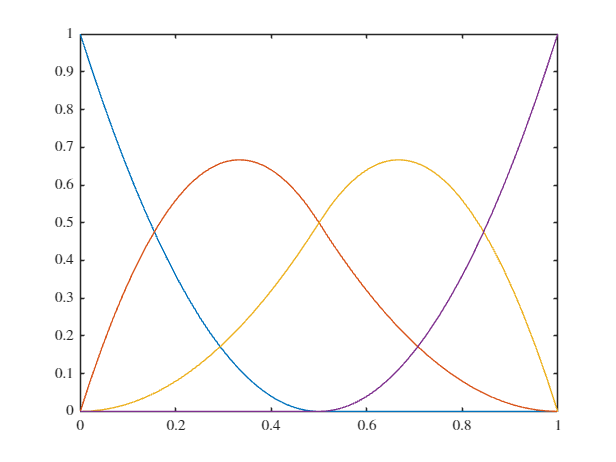

clear

x = sym( "x", "real" );
degree = [2, 2];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 1 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x ).Basis;

figure
fplot( basis, domain )


f(x) = 5*x^0;
g = 1;
h = 1;

U(x) = expand( ExactPoissonSolution( f, g, h, domain ).U )

$$U(x) = -\frac{5\,x^{2}}{2}+x+\frac{5}{2}$$

u(x) = PoissonEquation( spline_space, f, g, h )

$$u(x) = \left\{ \begin{array}{cl} -\frac{5\,x^{2}}{2}+x+\frac{5}{2} & \text{ if }x\in \left[0,1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

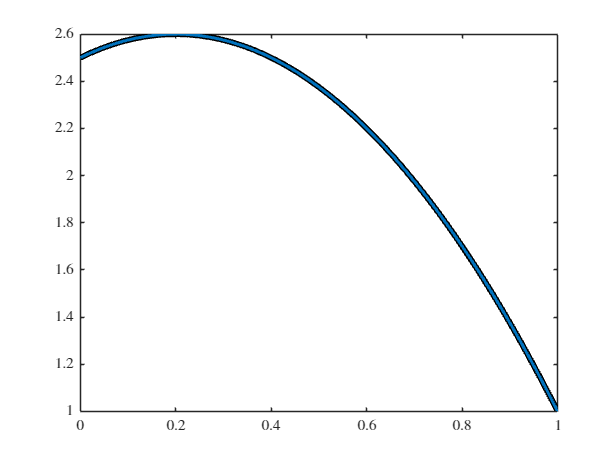


figure
hold on
fplot( U, domain, LineWidth=4, Color="k" )
fplot( u, domain, LineWidth=2, SeriesIndex=1 )

## Solving the Heat Equation with Galerkin's Method using Piecewise Polynomials 

clear

x = sym( "x", "real" );
thermal_conductivity = 100;
q(x) = 5*x^0;
g = 293.15;
h = 0;

degree = [2, 2];
domain = [ -12, 12 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 1 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x ).Basis;

T = ExactHeatSolution( thermal_conductivity, q, g, h, domain ).U

$$T(x) = \frac{6079}{20}-\frac{x\,\left(x+24\right)}{40}$$

t = HeatEquation( spline_space, thermal_conductivity, q, g, h )

$$t(x) = \left\{ \begin{array}{cl} -\frac{x^{2}}{40}-\frac{3\,x}{5}+\frac{6079}{20} & \text{ if }x\in \left[-12,12\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$


l2_error = ComputeL2Error( T, t, domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0$$

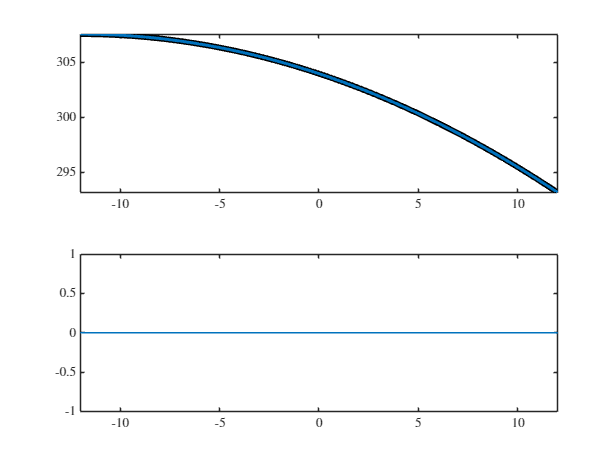


figure
subplot( 2, 1, 1 )
hold on
fplot( T, domain, LineWidth=4, Color="k" )
fplot( t, domain, LineWidth=2, SeriesIndex=1 )

subplot( 2, 1, 2 )
fplot( simplify( T - t )^2, domain )

## Solving the Euler–Bernoulli Equation with Galerkin's Method using Piecewise Polynomials 

clear

x = sym( "x", "real" );
youngs_modulus = sym( 200e9 );
moment_inertia = sym( 0.1 ) * sym( 0.1^3 ) / sym( 12 );
f(x) = 1e3 * x^1;
moment_load = 3e3;
shear_load = -5e3;
h = 0;
g = 0;

degree = [4, 4, 4];
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 3 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, x ).Basis;

figure
fplot( basis, domain, LineWidth=2 )

U = ExactBernoulliEulerBeamSolution( youngs_modulus, moment_inertia, f, moment_load, shear_load, domain ).U

$$U(x) = -\frac{x^{2}\,\left(x^{3}-110\,x+140\right)}{200000}$$

u = BernoulliEulerBeamEquation( spline_space, youngs_modulus, moment_inertia, g, h, f, moment_load, shear_load )

$$u(x) = \left\{ \begin{array}{cl} -\frac{x^{2}\,\left(3\,x^{2}-396\,x+502\right)}{720000} & \text{ if }x\in \left[0,\frac{1}{3}\right)\\ -\frac{x^{4}}{80000}+\frac{101\,x^{3}}{180000}-\frac{253\,x^{2}}{360000}+\frac{x}{810000}-\frac{1}{9720000} & \text{ if }x\in \left[\frac{1}{3},\frac{2}{3}\right)\\ -\frac{x^{4}}{48000}+\frac{7\,x^{3}}{12000}-\frac{29\,x^{2}}{40000}+\frac{x}{90000}-\frac{17}{9720000} & \text{ if }x\in \left[\frac{2}{3},1\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$


l2_error = ComputeL2Error( U, u, domain );
l2_error = vpa( simplify( abs( l2_error ) ), 16 )

$$l2\_error = 0.0000009049664242465077$$

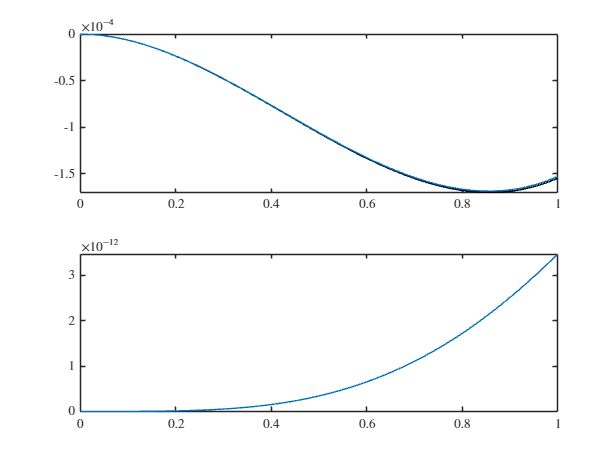


figure
subplot( 2, 1, 1 )
hold on
fplot( U, domain, Color="k" )
fplot( u, domain, SeriesIndex=1 )

subplot( 2, 1, 2 )
fplot( simplify( U - u )^2, domain )

## Solving the Spring Mass system with Galerkin's Method using Piecewise Polynomials 

function exactSolution = ExactDampedHarmonicOscillatorEquation( mass, damping, stiffness, force, displacement_constraint, slope_constraint, domain )
syms y(t)
eqn = mass*diff( y, t, 2 ) + damping*diff( y, t, 1 ) + stiffness*diff( y, t, 0 ) == force;
D1y = diff( y, t, 1 );
cond = [   y( domain(1) ) == displacement_constraint, ...
         D1y( domain(1) ) == slope_constraint ];
U(t) = dsolve( eqn, cond );

exactSolution.f = force;
exactSolution.eqn = eqn;
exactSolution.cond = cond;
exactSolution.domain = domain;
exactSolution.U = simplify( U, Steps=10 );
end

function [u, A, F, basis, d] = DampedHarmonicOscillatorEquation( spline_space, mass, damping, stiffness, force, displacement_constraint, slope_constraint )
variate = symvar( force );
SplineBasis = PiecewisePolynomialBasisFunction( spline_space, variate );
basis =  @(deriv) diff( SplineBasis.Basis, variate, deriv );
domain = spline_space.getSplineDomain();
[A, F] = ApplyGoverningEquations( basis, domain, mass, damping, stiffness, force );
[A, F] = ApplyBoundaryConditions( A, F, basis, domain, displacement_constraint, slope_constraint );
d = A \ F;
u = symfun( transpose( d ) * basis(0), variate );
u = simplify( u, Steps=10 );

    function [A, F] = ApplyGoverningEquations( basis, domain, mass, damping, stiffness, force )
        M = int( ( mass * basis(2) ) .* ( mass * transpose( basis(2) ) ), domain );
        C = int( ( mass * basis(2) ) .* ( damping * transpose( basis(1) ) ), domain );
        K = int( ( mass * basis(2) ) .* ( stiffness * transpose( basis(0) ) ), domain );
        A = M + C + K;
        F = int( ( mass * basis(2) ) * force, domain );
    end

    function [A, F] = ApplyBoundaryConditions( A, F, basis, domain, displacement_constraint, slope_constraint )
        [AD, FD] = DisplacementBoundaryCondition( basis, domain, displacement_constraint );
        [AN, FN] = SlopeBoundaryCondition( basis, domain, slope_constraint );
        A = A + AD + AN;
        F = F + FD + FN;
    end

    function [A, F] = DisplacementBoundaryCondition( basis, domain, displacement_constraint )
        A = subs( basis(0) .* transpose( basis(0) ),   symvar( basis(0) ), domain(1) );
        F = subs( basis(0) .* displacement_constraint, symvar( basis(0) ), domain(1) );
    end

    function [A, F] = SlopeBoundaryCondition( basis, domain, slope_constraint )
        A = limit( basis(1), variate, domain(1), "right" ) .* transpose( limit( basis(1), variate, domain(1), "right" ) );
        F = limit( basis(1), variate, domain(1), "right" ) .* slope_constraint;
    end

end

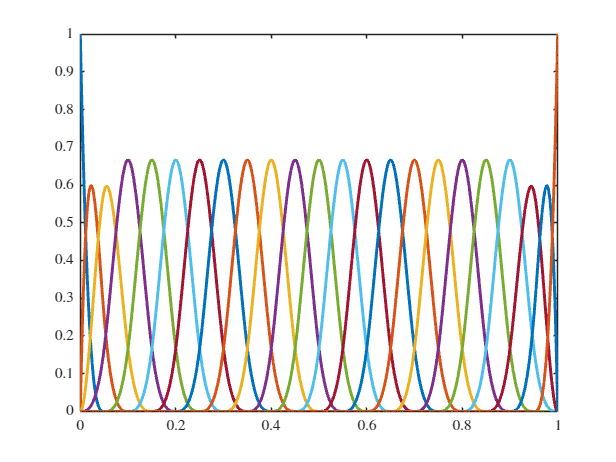

clear

t = sym( "t", "real" );
mass = sym( 20.4 );
damping = sym( 250 );
stiffness = sym( 29.5e3 );
force(t) = -sym( 21.6 ) * t^0;
h = sym( 0 );
g = sym( 0 );

degree = 3 * ones( 1, 20 );
domain = [ 0, 1 ];
vertices = linspace( domain(1), domain(2), length( degree ) + 1 );
continuity = [ -1, 2 * ones( 1, length( degree ) - 1 ), -1 ];
spline_space = SplineSpace( degree, vertices, continuity );
basis = PiecewisePolynomialBasisFunction( spline_space, t ).Basis;

figure
fplot( basis, domain, LineWidth=2 )

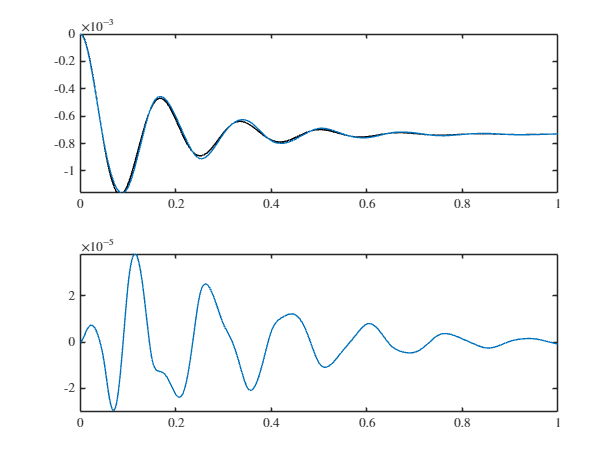


U = ExactDampedHarmonicOscillatorEquation( mass, damping, stiffness, force, g, h, domain ).U;
u = DampedHarmonicOscillatorEquation( spline_space, mass, damping, stiffness, force, g, h );

% l2_error = ComputeL2Error( U, u, domain );
% l2_error = vpa( simplify( abs( l2_error ) ), 16 )

figure
subplot( 2, 1, 1 )
hold on
fplot( U, domain, Color="k" )
fplot( u, domain, SeriesIndex=1 )

subplot( 2, 1, 2 )
fplot( simplify( U - u ), domain )

Timing

time_fun = @()DampedHarmonicOscillatorEquation( spline_space, mass, damping, stiffness, force, g, h );
t_elapsed = timeit( time_fun, 1 );
disp( "Elapsed time: " + num2str( t_elapsed, 2 ) )

Elapsed time: 56
